# Linear Control Design II - Group Work Problem Module 2 Solution

## Description

In Figure 1 an electro-mechanical system is illustrated. The mechanical part is composed of a flexible structure buit by three masses interconnected by flexible beams. The electrical part is composed of a pair of electromagnets. The lateral movements of the lower mass is coupled to the pair of electromagnets by means of the electromagnetic forces generated in the small gap illustrated in Figure 2. It means there is no mechanical contact between the two parts. The main goal is: a) to build an electro-mechanical model based on simplifying assumptions; b) to build a mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday; c) to build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t),\,\,x_2(t),\,\,x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$; d) investigate the vibrations of the structure when different initial conditions and inputs are present.

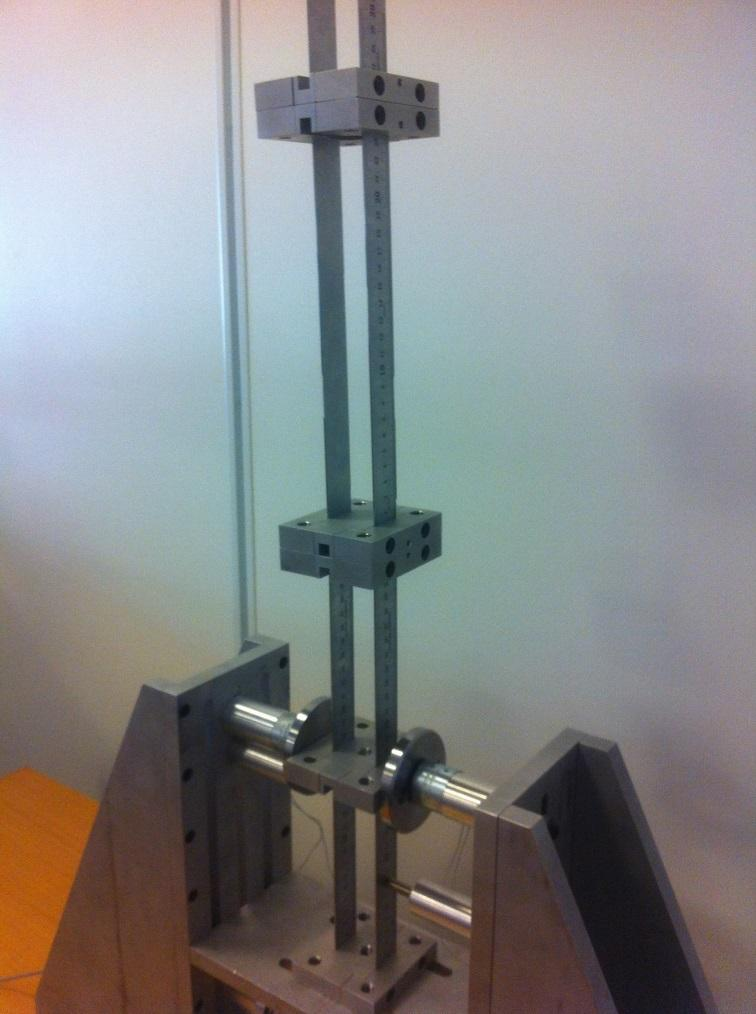


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


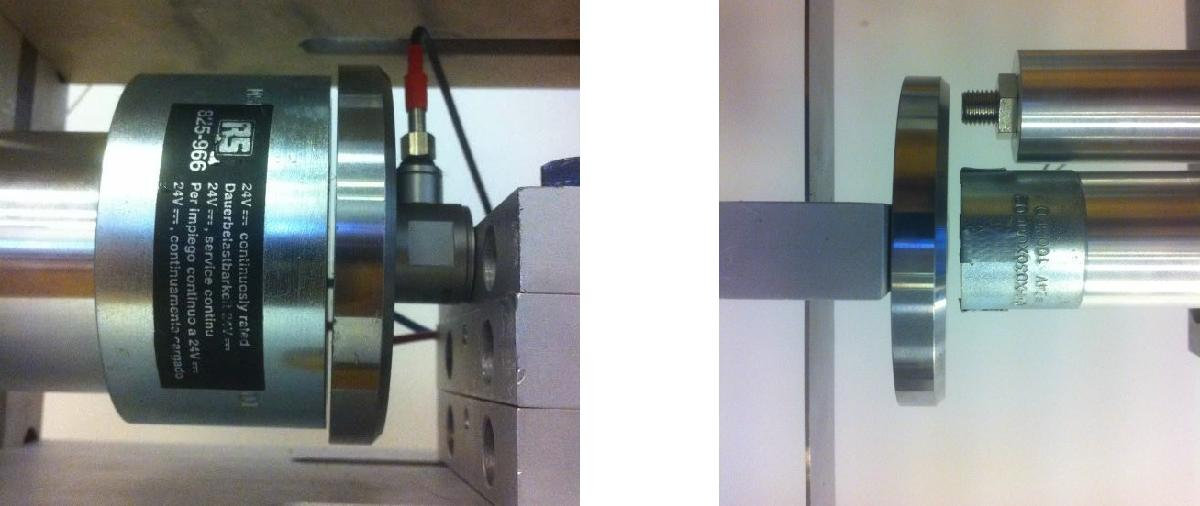


$$(a)\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad (b)$$



$$Figure\,2:\,The\,electro parts:\,(a)\,one\,single\,electromagnet\,and\,the\,gap\,where\,the\\ electromagnetic\,force\,will\,be\,generated\,by\,the\,input\,voltage\,u(t);\,(b)\,electromagnetic\\ actuator\,and\,eddy-current\,displacement\,sensor\,using\,to\,control\,and\,to\,measure\,the\\ lateral\,movements\,of\,the\,lower\,mass.$$


For the simulations the following parameters are given.

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

R = 148.2; % [Ohm]
L = 800e-3; % [H]

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

Ki5 = 22.4;
Ks5 = -313.6;

Ki3 = 37.33;
Ks3 = -871.11;

Ki2 = 56;
Ks2 = -1.96e3;

Ki1 = 112;
Ks1 = -7.84e3;

Where $Ki\#$ indicates the magnitude of the linearized force dependent on current change when the air gap $s_0$=$\#$ mm.

**Problem 1**

Build an electro-mechanical model based on simplifying assumptions.

**Solution****:**

The beams of the structure can be simplified as simple massless linear springs. When a spring is compressed the reaction forces will point away from the center of the spring while the reaction forces will point towards the center when the spring is extended.

The lateral dynamics of the three masses is described based on Newtons 2nd law. There are three types of forces to be considered: a) the linear spring forces which are proportional to the relative displacement between the masses described by the stiffness coefficients $k_1$, $k_2$, and $k_3$; b) the electromagnetic force $f(t)$acting on the lowest mass which is depending on the gap variation and current described by the coefficients ks and ki ; and finally c) the inertia forces whcih are depending on the absolute linear acceleration of the masses  described by  their masses.  The mechanical and electrical models are shown in Figure 3. As the actuator is an electromagnet the dynamics of the actuators can be described from Faraday's law.

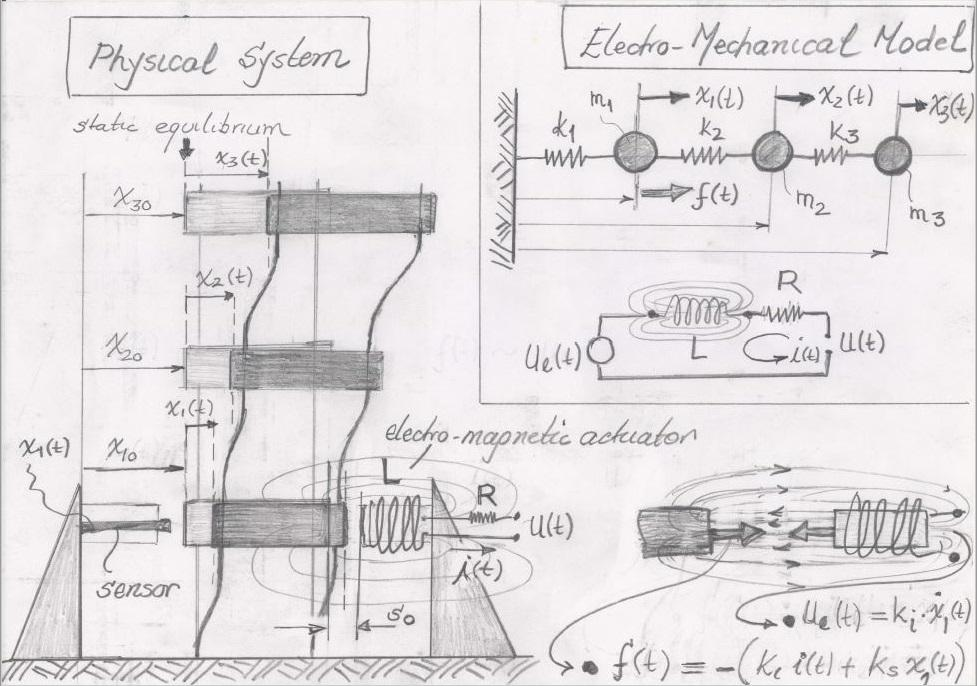


$$Figure\,3:\ Mechanical\,and\,electrical\,models $$


**Problem 2**

Build the mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday, based on the electro-mechanical model and simplifying assumptions done in problem 1.Use as main variables the  three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.

**Solution****:**

The differential equations in Figure 4 describe the lateral dynamics of the flexible structure, i.e. the accelerations of the three masses  $\ddot{x}_1(t)$, $\ddot{x}_2(t)$ and $\ddot{x}_3(t)$, and the dynamic behavior of the current $\dot{i}(t)$ in the electrical circuit composed of resistance $R$, inductance $L$, the input voltage $u(t)$ and the induced current due to the linear velocity of the lowest mass (which will also induce the electromagnetic force). The differential equations are derived from the electro-mechanical model.

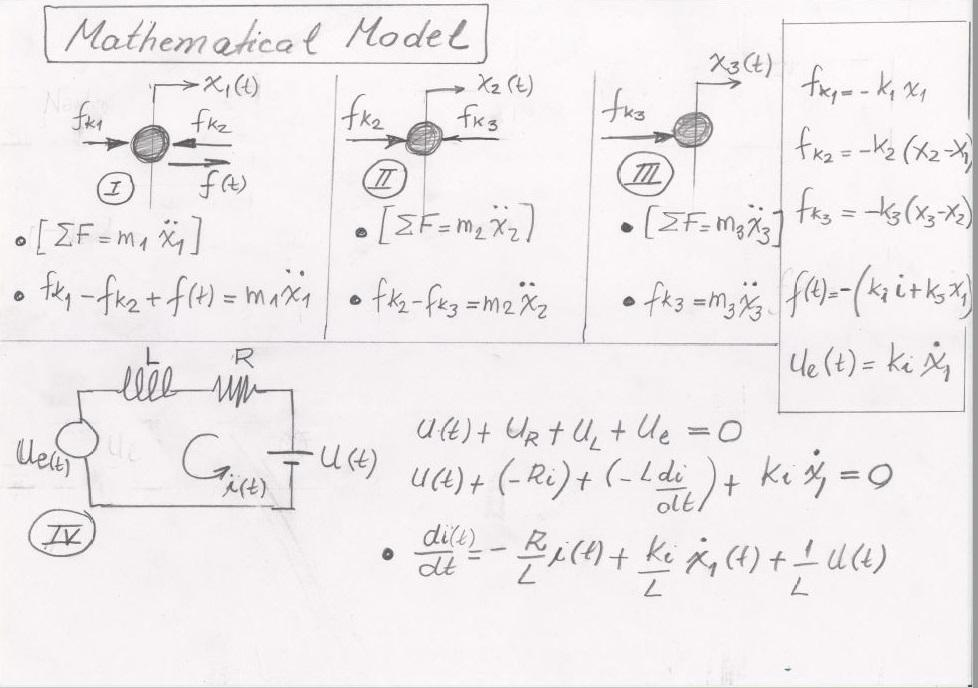


$$Figure\,4:\,The\,global\;mathematical\,model$$


**Problem 3**

Build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.

**Solution****:**

The simulink diagram deducted from the mathematical model and used for the simulations is presented in Figure 5.

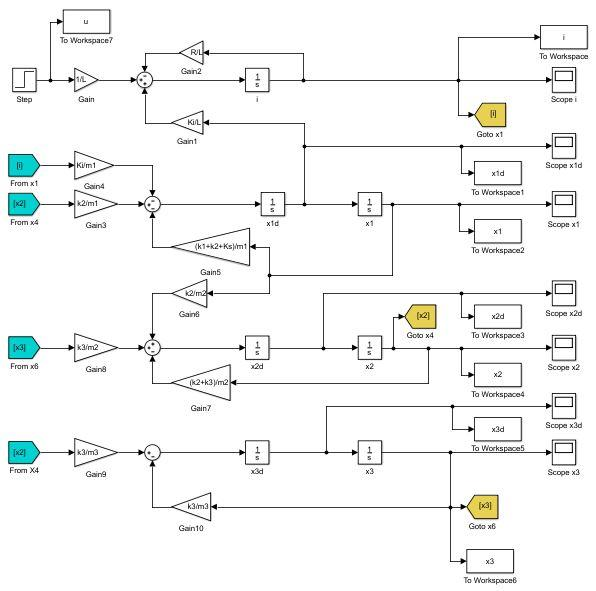


$$Figure\,5:\,The\,simulink\,diagram\,used\,to\,simulate\,the\,coupled\,dynamics\\ between\,the\,lateral\,movements\,of\,the\,three\,masses\,x_1(t),\,x_2(t),\,x_3(t)\,and\\ the\,current\,i(t)\,induced\,in\,the\,coils\,depending\,on\,the\,electrical\,potential\,u(t)$$


**Problem 4**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results.

**Solution****:**

**4a)** Behavior of system when $s_0$=5 mm

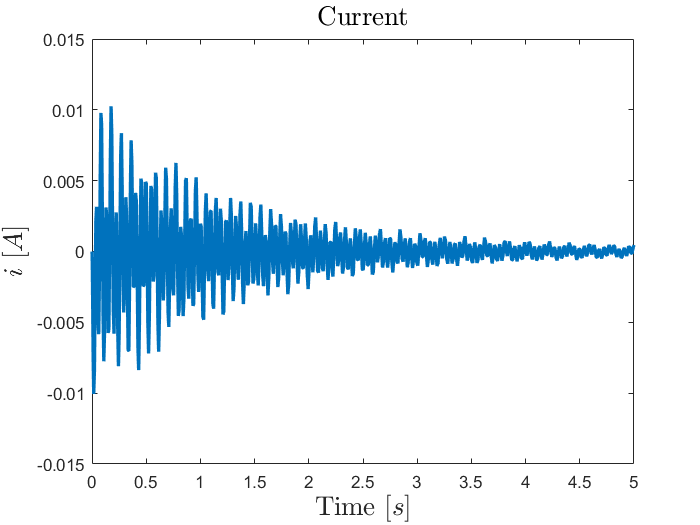

Ki = Ki5;
Ks = Ks5;

% initial conditions
x_0 = [0 0.001 0 0 0 0 0]';

% input
u_0 = 0;
      
%% Simulations
sim('electroMagnetModel');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');

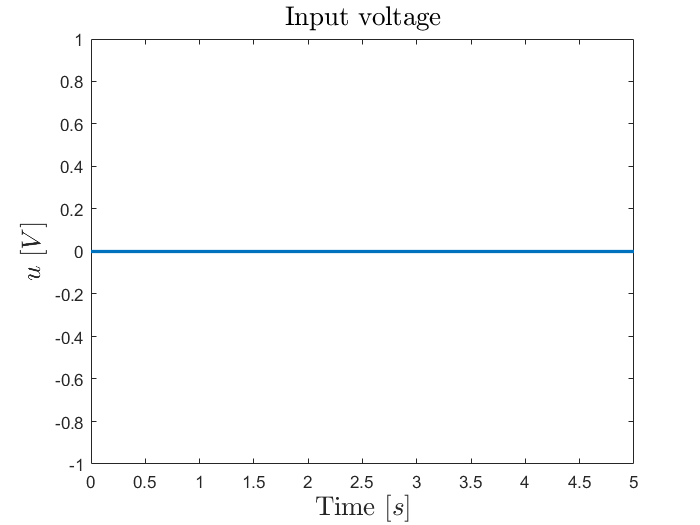


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

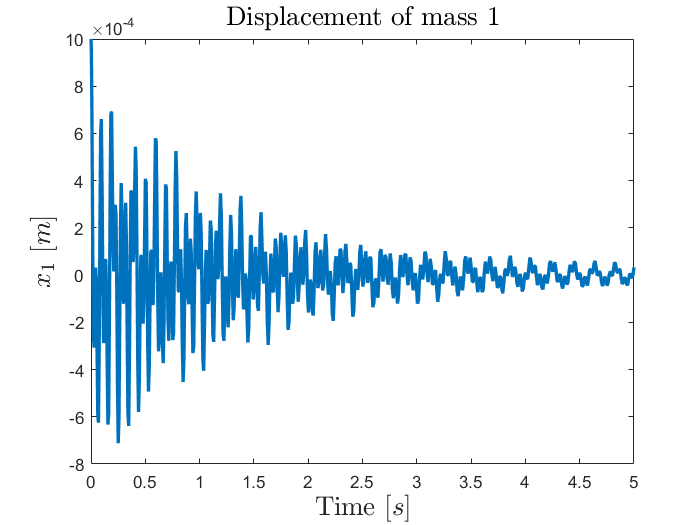


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

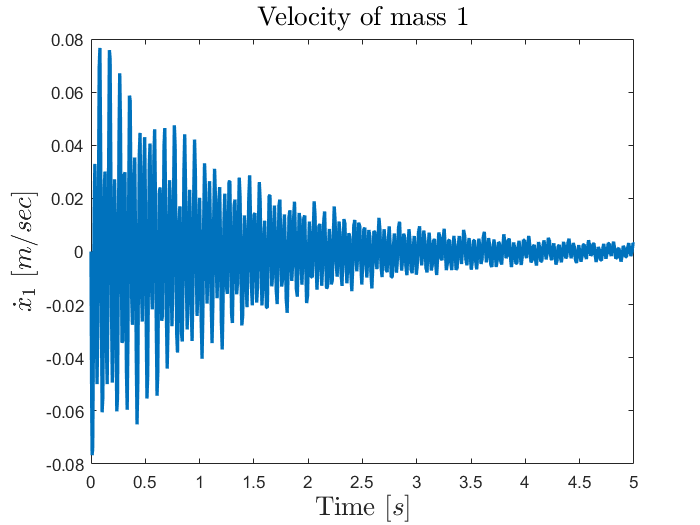


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

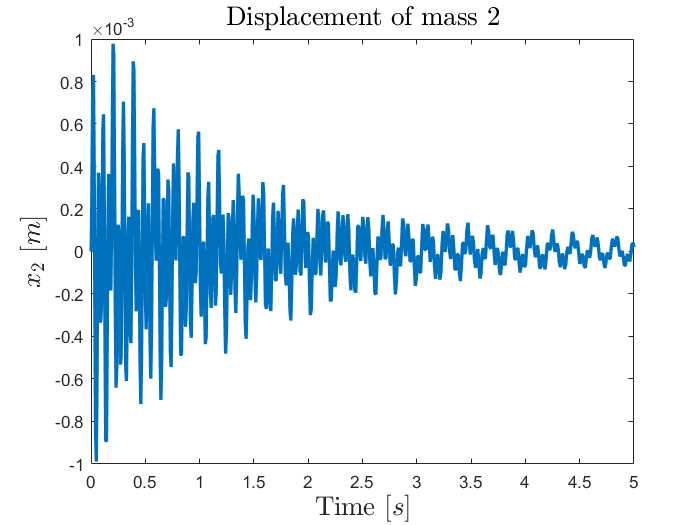


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

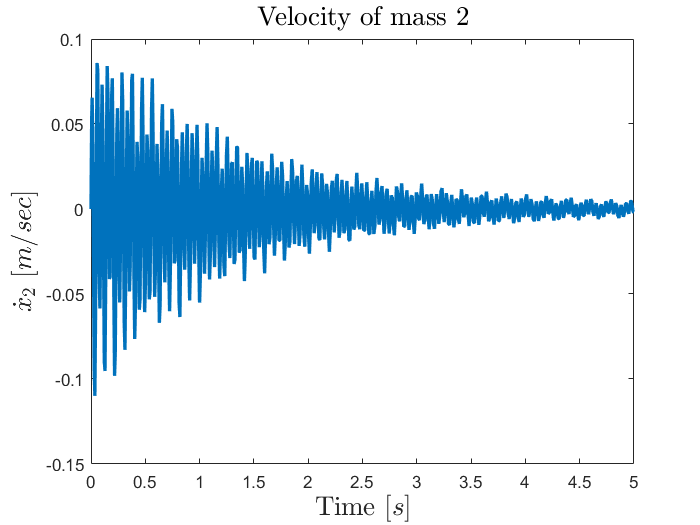


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

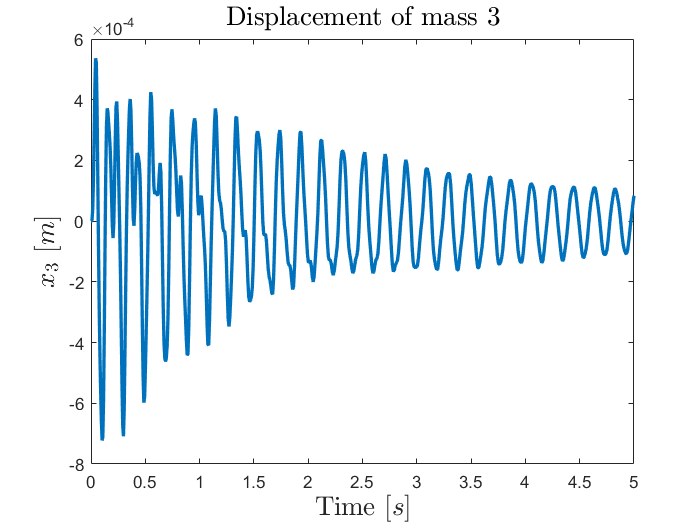


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

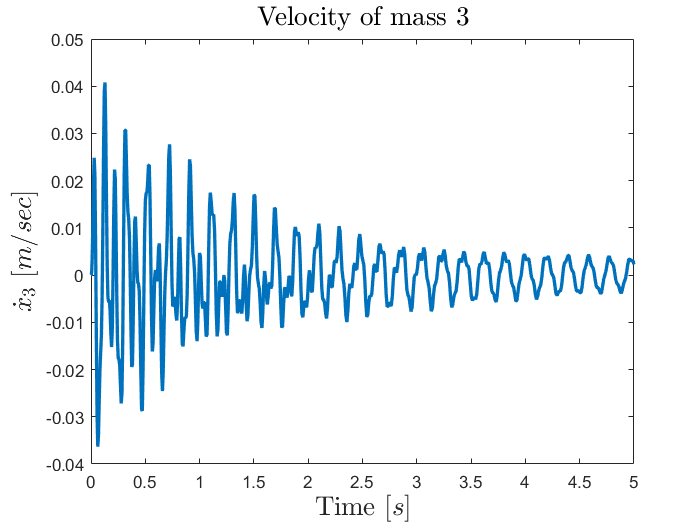


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

As we can see in the plots, when there is no external input (voltage or forces) acting on the system, the responses decay over time to their equilibrium positions, i.e. zero displacement,  zero velocity and zero current. This is expected, since the system is very similar to the mass-spring-damper system. After approximately 10 seconds all the transient behaviors of the states have died out and the state settle to its equilibrium point $\textbf{x}(t) = [0\; 0\; 0\;  0\;  0 \;0 \; 0]^T$.

**4b) **Behavior of system when $s_0$=3 mm

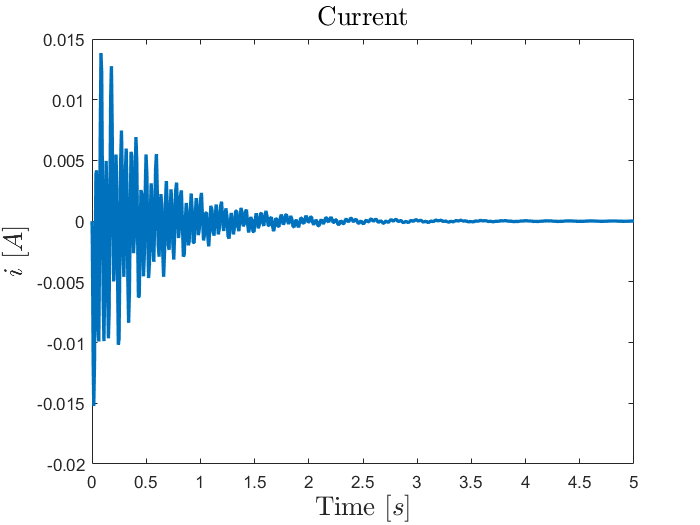

Ki = Ki3;
Ks = Ks3;

%% Simulations
sim('electroMagnetModel');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

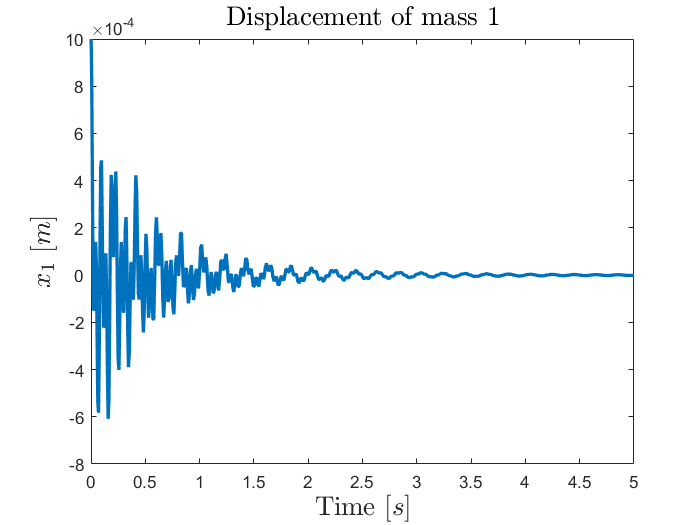


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

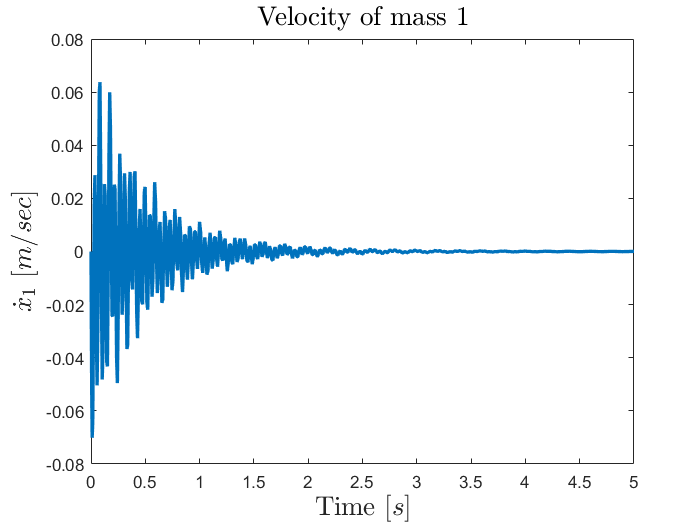


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

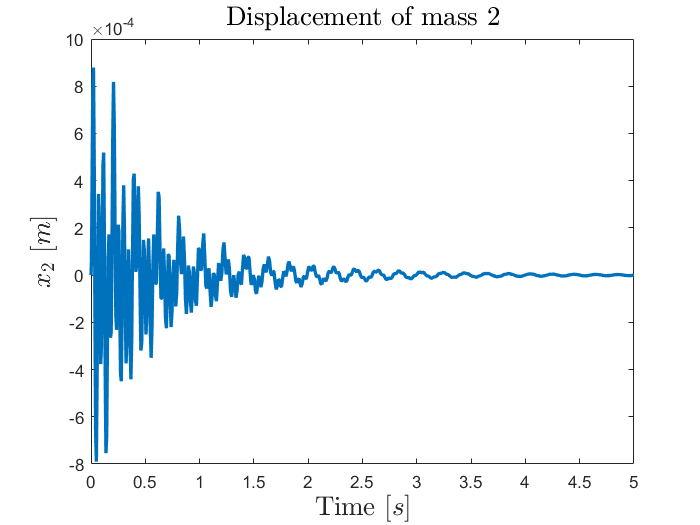


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

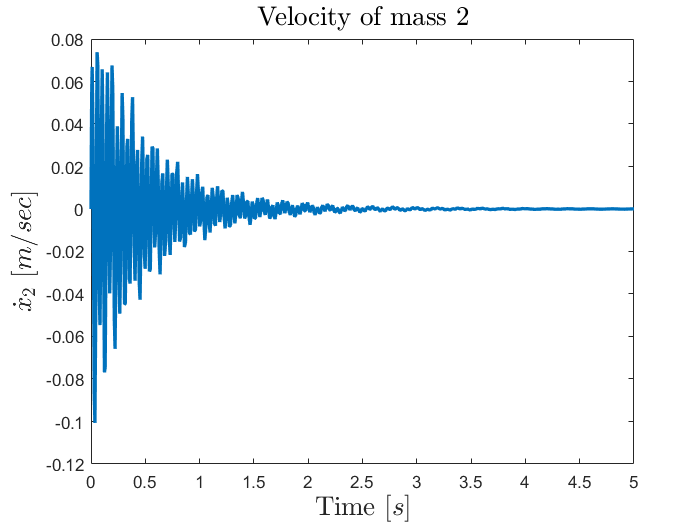


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

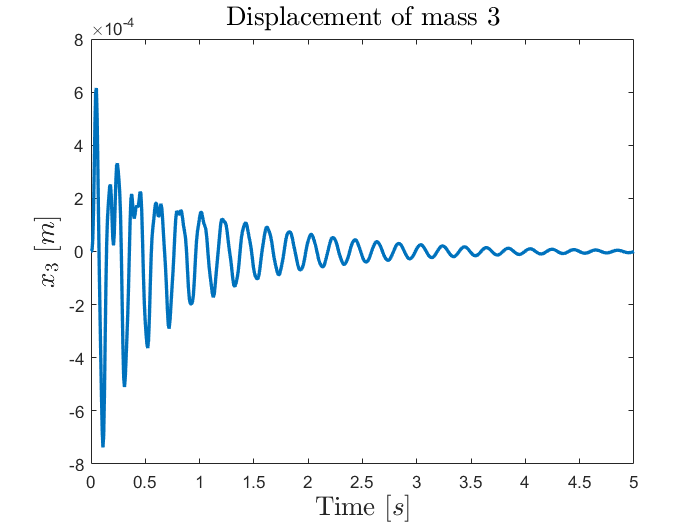


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

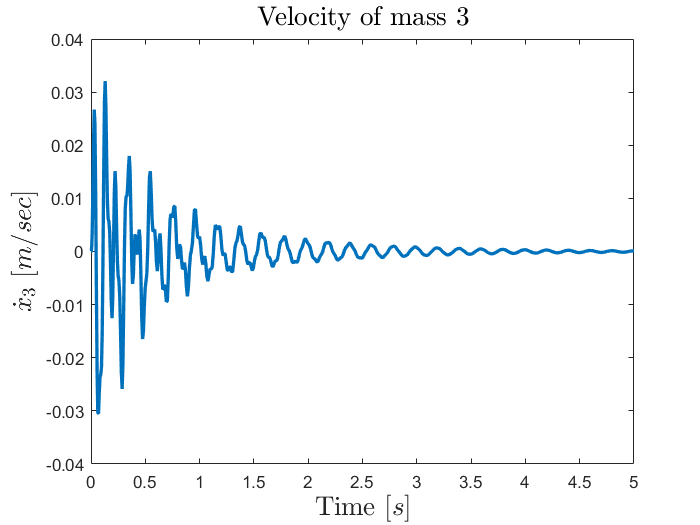


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

The behavior of the system is similar to the previous case with the difference that the state variables now settle to their equilibrium positions much faster, almost in 3 seconds. This can be explained by the fact that smaller air gaps between the lowest mass and the magnets generate larger magnetic forces, which in turn drive the system dynamics faster. This will be better understood next class when the nonlinar expression for the electro-magnetic forces will be presented depending on the gap and current. 

**4c) **Behavior of system when $s_0$=1 mm

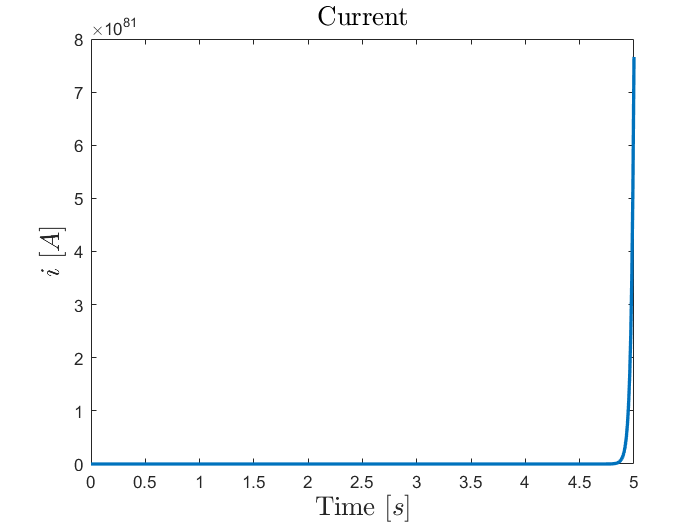

Ki = Ki1;
Ks = Ks1;
   
%% Simulations
sim('electroMagnetModel');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

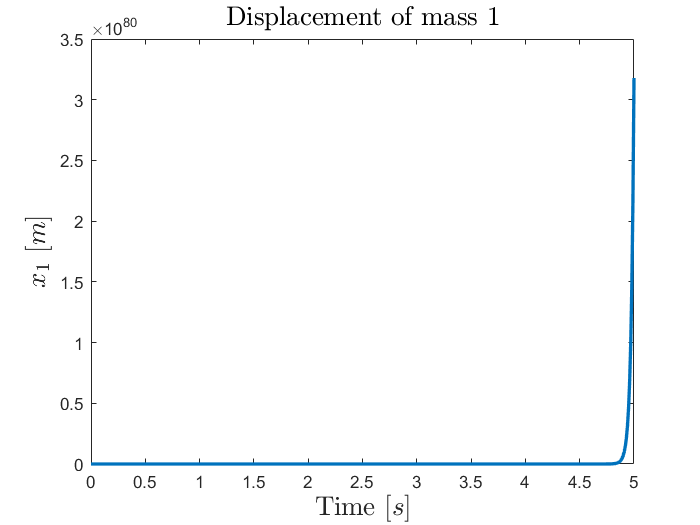


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

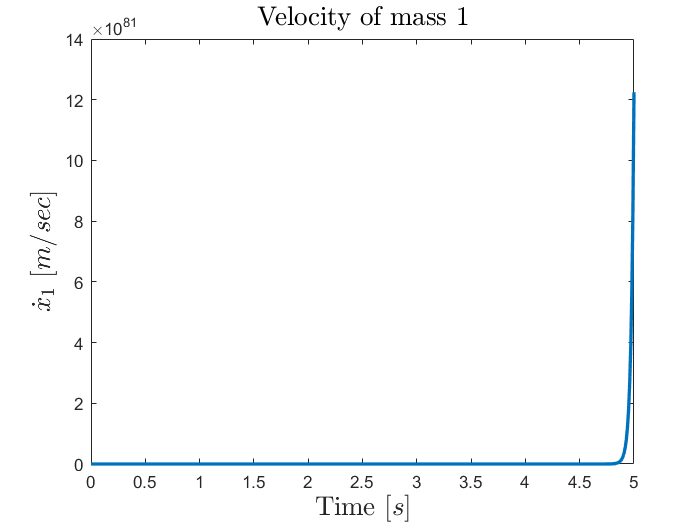


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

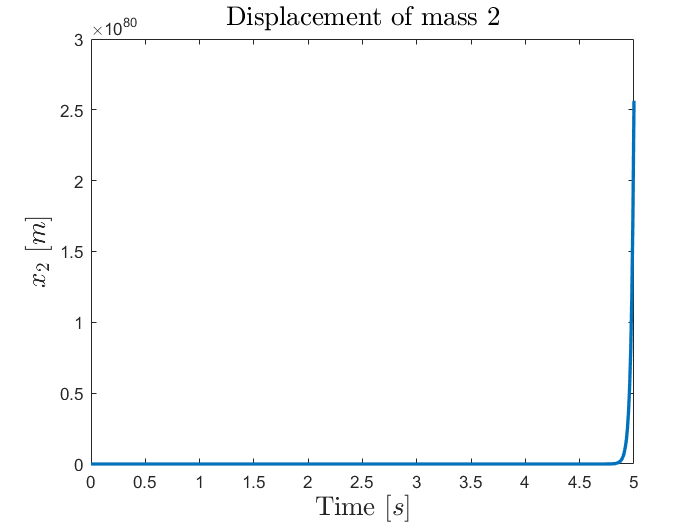


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

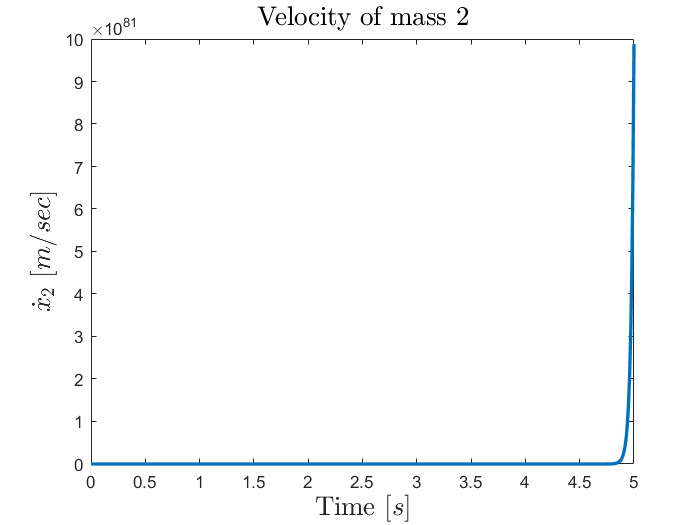


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

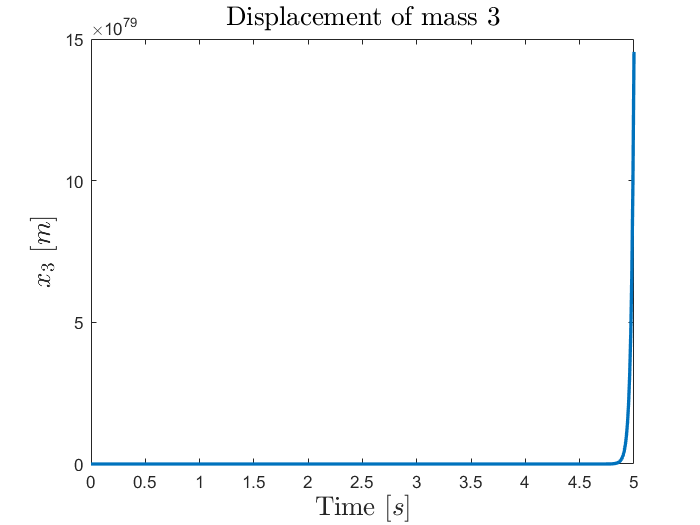


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

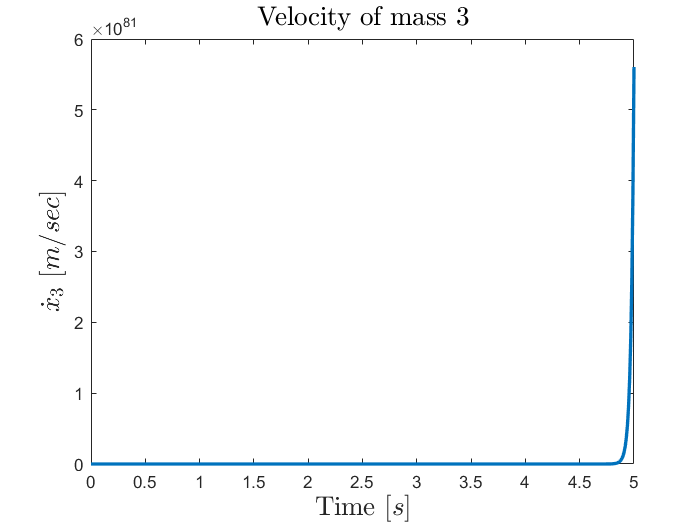


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

Last, the system is simulated with $s_0$=1 mm. As it can be seen in the plots the system becomes unstable, i.e. the state variables do not settle to any equilibrium point but they keep growing unbounded. This can be explained by the fact that in very small distances the magnetic force is too large to allow the system to settle anywhere. Of course if the plots were real sensor data,  we should expect to see the states reaching a saturation level since the system is physically constraint. 

**Problem 5**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

**Solutio****n****:**

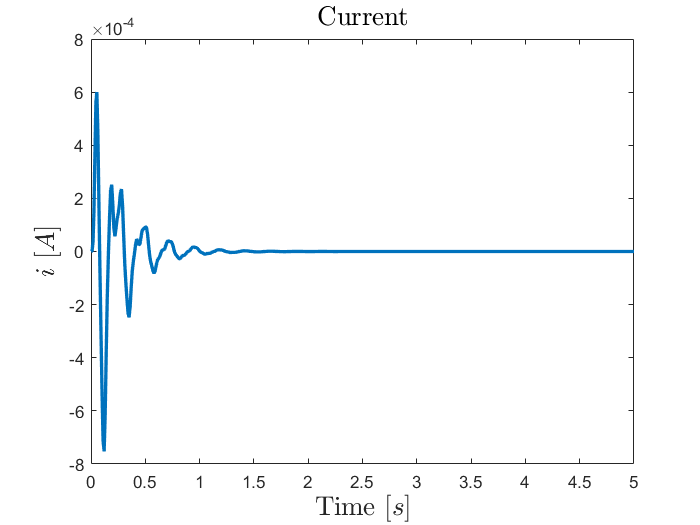

% initial conditions
x_0 = [0 0 0 0 0 0 0.005]';

Ki = Ki2;
Ks = Ks2;

%% Simulations
sim('electroMagnetModel');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

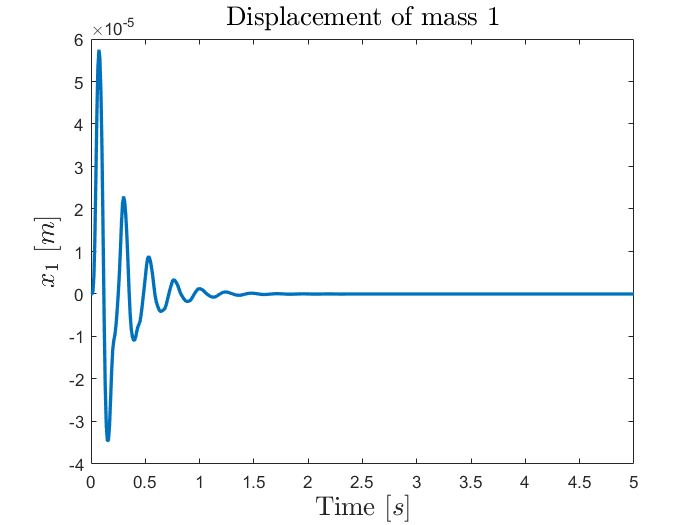


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

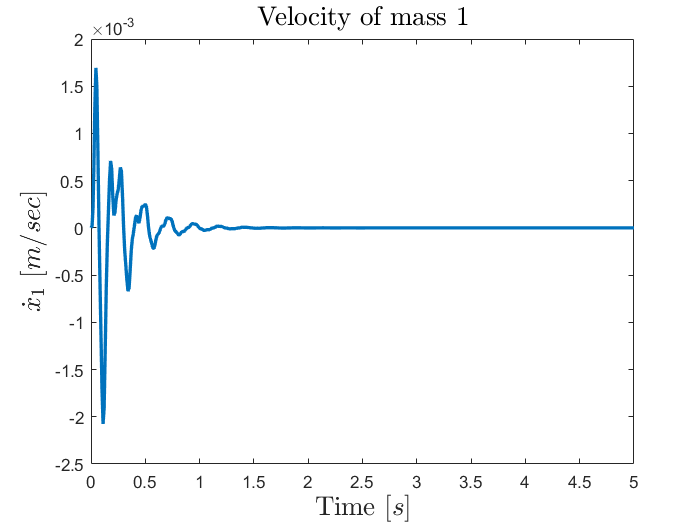


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

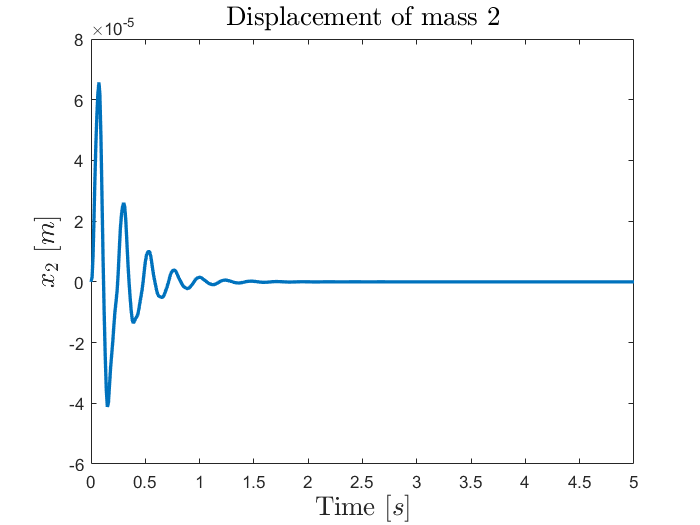


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

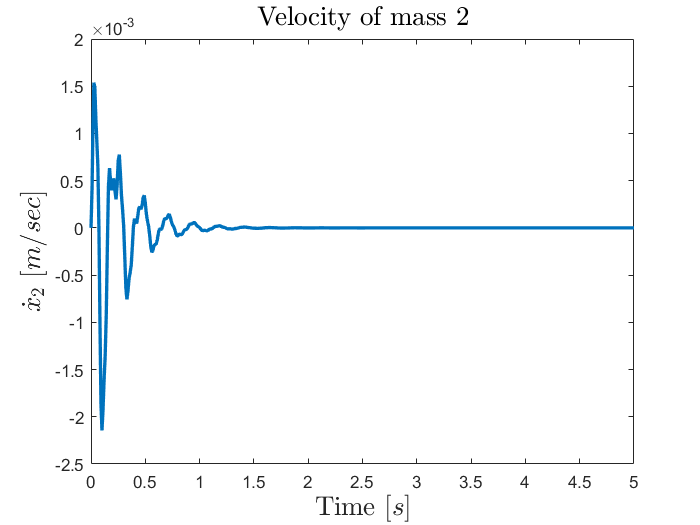


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

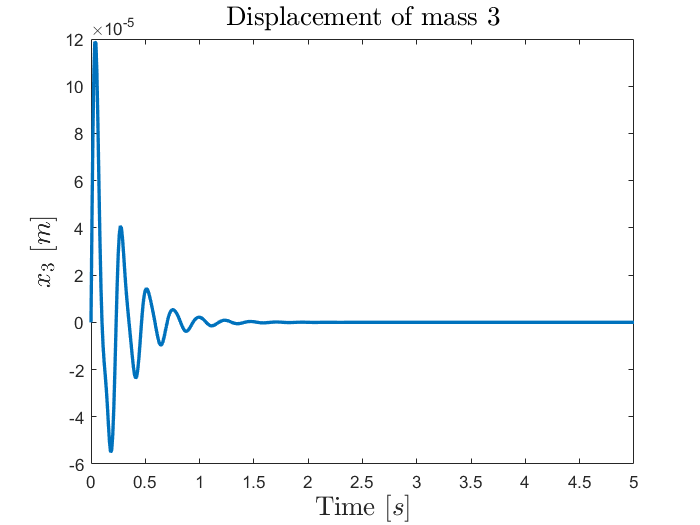


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

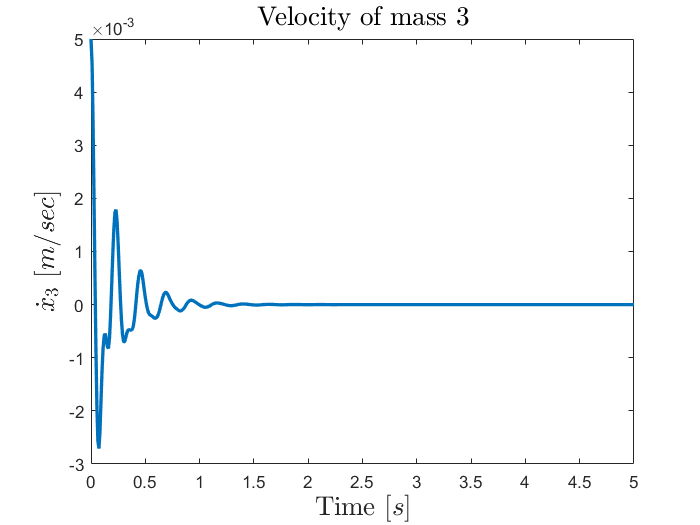


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

From the time response of the state variables corresponding to the displacement of the masses from the simulation (the three plots on the left hand side) we can measure the maximum displacement for each mass as


$$x_{1,max}=5.74\cdot10^{-5}m\\
x_{2,max}=6.57\cdot10^{-5}m\\
x_{3,max}=1.18\cdot10^{-5}m$$


The displacement of the third (upper) mass is larger, almost double, in comparison to the other displacements. This is expected since the third mass on the top of the structure is globally more flexible, accumulating the deflection of the two lower masses. 

**Problem 6**

A step function $u(t)$=10 V is send to the electromagnets, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies.

**Solution****:**

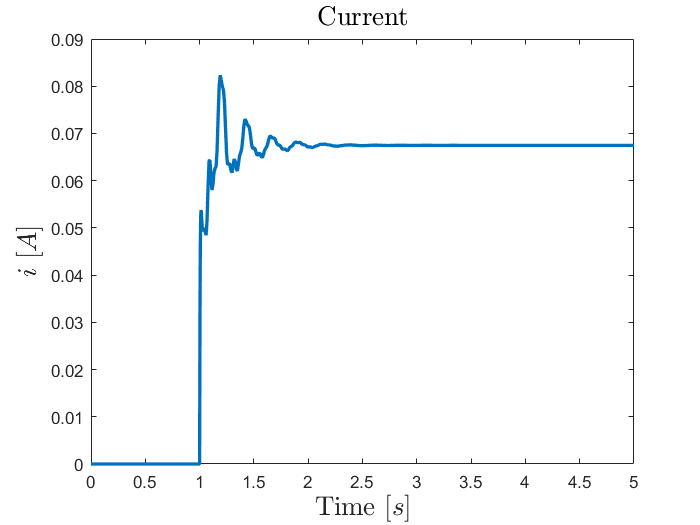

% initial conditions
x_0 = [0 0 0 0 0 0 0]';

% input
u_0 = 10;

%% Simulations
sim('electroMagnetModel');

%% Plots
time = i.time;

figure
plot(time,i.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$i$ $[A]$', 'FontSize',16,'Interpreter','latex');
title('Current', 'FontSize',16,'Interpreter','latex');

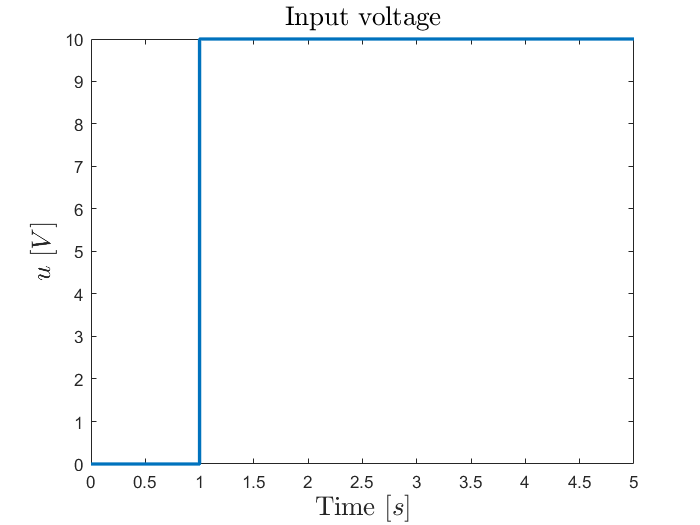


figure
plot(time,u.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$u$ $[V]$', 'FontSize',16,'Interpreter','latex');
title('Input voltage', 'FontSize',16,'Interpreter','latex');

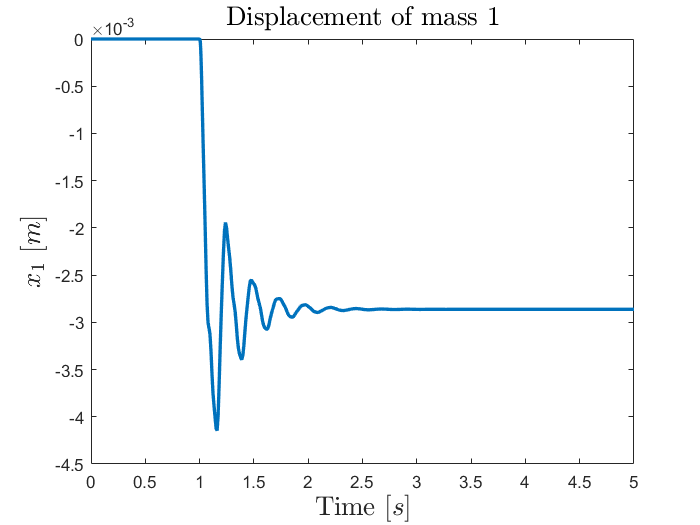


figure
plot(time,x1.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_1$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 1', 'FontSize',16,'Interpreter','latex');

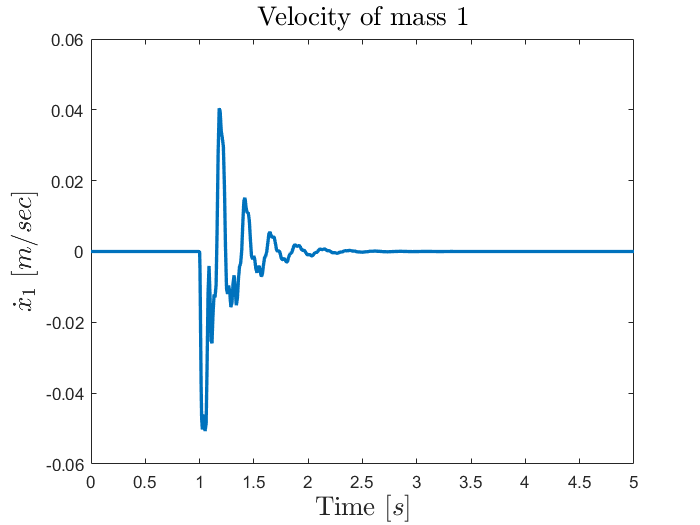


figure
plot(time,x1d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 1', 'FontSize',16,'Interpreter','latex');

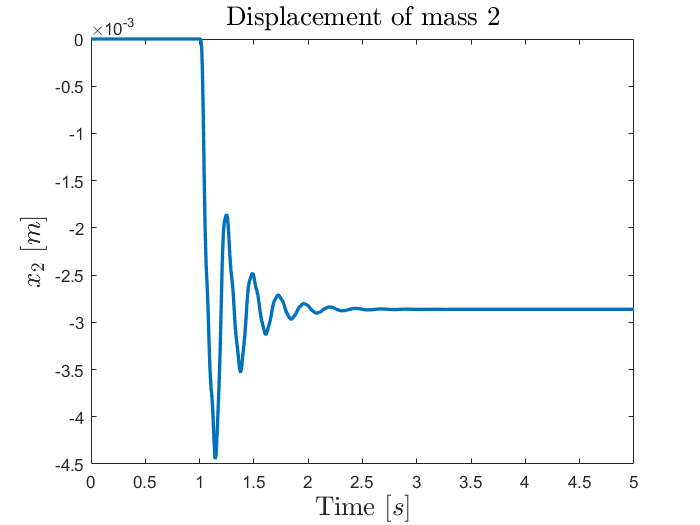


figure
plot(time,x2.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_2$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 2', 'FontSize',16,'Interpreter','latex');

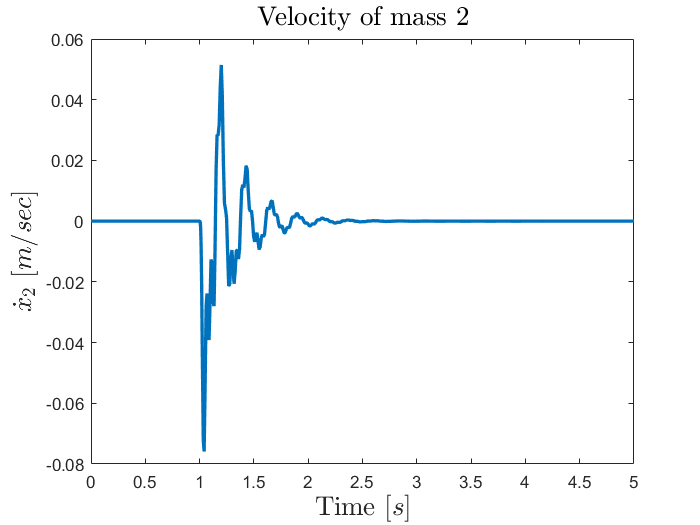


figure
plot(time,x2d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 2', 'FontSize',16,'Interpreter','latex');

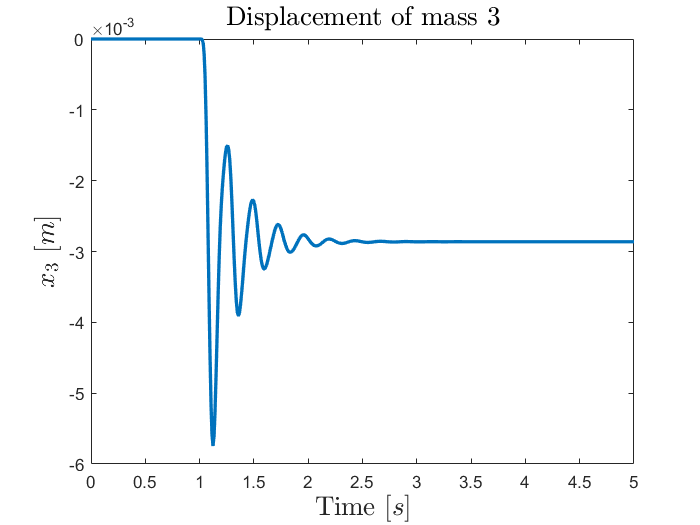


figure
plot(time,x3.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$x_3$ $[m]$', 'FontSize',16,'Interpreter','latex');
title('Displacement of mass 3', 'FontSize',16,'Interpreter','latex');

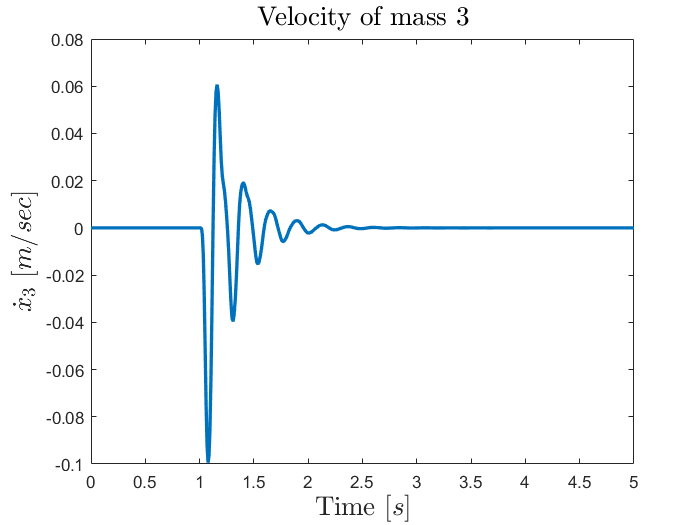


figure
plot(time,x3d.signals.values, 'LineWidth', 2);
xlabel('Time $[s]$', 'FontSize',16,'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$', 'FontSize',16,'Interpreter','latex');
title('Velocity of mass 3', 'FontSize',16,'Interpreter','latex');

As it is shown by the plots, after the transient behavior of the states has died out, the latter settle at a constant steady-state value. The velocities, as expected settle to zero, while the positions assume a nonzero value since there is a constant voltage that keeps exciting the system. The transient behavior can be described as a fading oscillatory response, which is expected, given that there is damping in the system. From the plots, by measuring the period (approximately) of the oscillations and the amplitude of the responses we can approximate the magnitude and the frequency of the signals. In the next lectures, when the modal analysis will be introduced, the relation between the oscillatory behavior of the responses and the eigenvalues of the system matrix $\textbf{A}$ will provide an accurate method of calculating the frequencies and amplitudes of the state responses.